clc; clear;
% 基本参数设置  
Fs = 2e3; % 采样频率，可设置其他
T = 1/Fs;  % 采样周期
L = 128;  % 信号长度，可设置其他
t = (0:L-1)*T; % 时间向量 
delta_f = Fs/L; %采样间隔
f0 = 5e2; %选定的一个落在采样点上的频率，也可设置其他
A = sqrt(2);  % 振幅，使得信号功率为1，也可设置其他
phi_0 = 0;   % 相位，可设置其他
n = 1000;%蒙特卡洛实验次数，可设置其他

%x轴为不同频率的仿真（适用'高/低信噪比情况下不同频点的仿真'、'无噪声时仿真'、'窗函数'等基于频率的仿真）

f = f0-delta_f/2:delta_f/20:f0+delta_f/2;%更改待检测频率的范围，所示为从选定的采样点到两侧采样点中心，以1/20个采样间隔为单位等间距取点
x_f = ones(length(f),L); %预先设置待测信号矩阵的大小
for j = 1:length(f) %利用预先设置的参数生成待测信号
    x_f(j,:) = A*sin(2*pi*f(j)*t + phi_0);
end

P_signal = 0.5*A^2;%待测信号功率
%设置SNR的大小，可考虑0dB为低信噪比，10dB为高信噪比情况
snr = 0;%若希望无噪声，则预先设置蒙特卡洛仿真次数为n=1,设置snr = Inf
sigma = sqrt(P_signal*(10^(-snr/10))); %计算sigma，方便后续生成高斯噪声

%预先设置窗函数的类型
window = hann(L);%汉宁窗
% window = hamming(L);%哈明窗
% window = blackman(L);%布莱克曼窗
% window = blackmanharris(L);%布莱克曼-哈里斯窗
% window = kaiser(L);%凯赛窗

%预先设置频率估计RMS值的矩阵大小，用RMS值代表估计频率大小
RMS_Dirc = ones(1,length(f));%直接估计算法
RMS_Rife= ones(1,length(f));%Rife算法
RMS_Irife = ones(1,length(f));%Irife算法
RMS_AIrife = ones(1,length(f));%AIrife算法
RMS_Quinn = ones(1,length(f));%Quinn算法
RMS_Quinn_About = ones(1,length(f));%改进Quinn算法

%预先设置频率估计方差的矩阵大小，用方差衡量频率估计的稳定性
Var_Dirc = ones(1,length(f));%直接估计算法
Var_Rife= ones(1,length(f));%Rife算法
Var_Irife = ones(1,length(f));%Irife算法
Var_AIrife = ones(1,length(f));%AIrife算法
Var_Quinn = ones(1,length(f));%Quinn算法
Var_Quinn_About = ones(1,length(f));%改进Quinn算法

x_I = sin(2*pi*(f0+delta_f/2)*t + pi/2);

for j = 1:length(f)
    x = ones(n,L);
    for k = 1:n
        %x(k,:) = x_f(j,:) + sigma^2*randn([1,L]); %选用高斯噪声
        x(k,:) = (x_f(j,:) + sigma^2*randn([1,L])).*window';%加窗函数,附加高斯噪声
    end

    %预先设置好频率估计的矩阵大小
    f_est_Dirc = ones(1,n);
    f_est_Rife = ones(1,n);
    f_est_Irife = ones(1,n);
    f_est_AIrife = ones(1,n);
    f_est_Quinn = ones(1,n);
    f_est_Quinn_About = ones(1,n);

    %运行频率估计算法
    for m = 1:n    
        f_est_Dirc(m) = Dirc_esti(x(m,:),t);
        f_est_Rife(m) = Rife_esti(x(m,:),t);
        f_est_Irife(m) = Irife_esti(x(m,:),t);       
        f_est_AIrife(m) = AIrife_esti(x(m,:),t); 
        f_est_Quinn(m) = Quinn_esti(x(m,:),t);
        f_est_Quinn_About(m) = Quinn_About_esti(x(m,:),t);       
    end

    %计算RMS值
    RMS_Dirc(1,j) = sqrt(sum(f_est_Dirc.^2)/n);
    RMS_Rife(1,j) = sqrt(sum(f_est_Rife.^2)/n);
    RMS_Irife(1,j) = sqrt(sum(f_est_Irife.^2)/n);  
    RMS_AIrife(1,j) = sqrt(sum(f_est_AIrife.^2)/n);  
    RMS_Quinn(1,j) = sqrt(sum(f_est_Quinn.^2)/n);
    RMS_Quinn_About(1,j) = sqrt(sum(f_est_Quinn_About.^2)/n);

    %计算方差
    Var_Dirc(1,j) = var(f_est_Dirc);
    Var_Rife(1,j) = var(f_est_Rife);
    Var_Irife(1,j) = var(f_est_Irife);  
    Var_AIrife(1,j) = var(f_est_AIrife);  
    Var_Quinn(1,j) = var(f_est_Quinn);
    Var_Quinn_About(1,j) = var(f_est_Quinn_About);
end
Var_CRLB = 6*Fs^2/(4*pi^2*10^(snr/10)*L*(L^2-1));%计算频率估计的CRLB下界
%！！！这个是信号幅度、频率、相位均未知时的公式，按理说不适用，所以可考虑不用

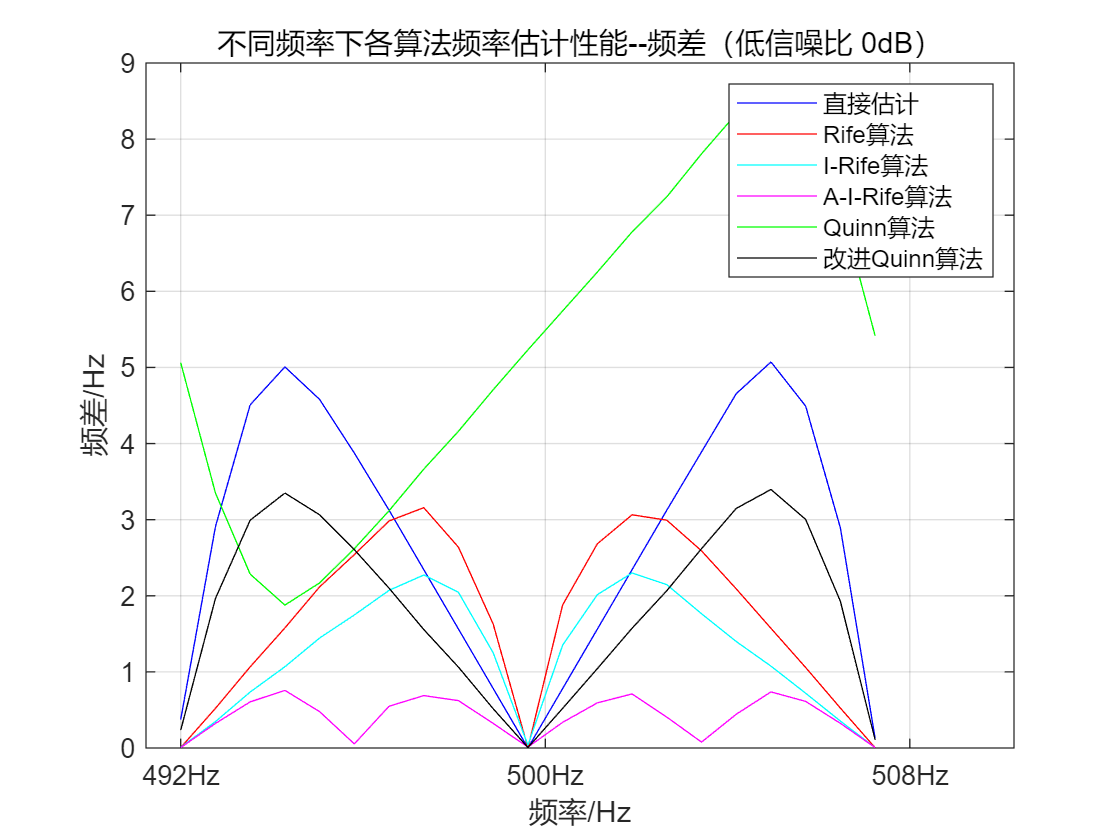

close all;
%绘图，频差的仿真图象
figure(1);
%具体采用线性坐标还是对数坐标，要看实际的图像适合哪个，可在图窗界面自行设置选项，以及，曲线的选项同理
plot(1:length(f),abs(RMS_Dirc-f),'b');
hold on;
plot(1:length(f),abs(RMS_Rife-f),'r');
hold on;
plot(1:length(f),abs(RMS_Irife-f),'c');
hold on;
plot(1:length(f),abs(RMS_AIrife-f),'m');
hold on;
plot(1:length(f),abs(RMS_Quinn-f),'g');
hold on;
plot(1:length(f),abs(RMS_Quinn_About-f),'k');
%以下参数是为了方便手动设置图像的部分选项，仅供参考，可直接忽略，后续可在图窗界面设置
xticks([1 1+length(f)/2 1+length(f)]);
xticklabels({'492Hz','500Hz','508Hz'});
xlabel('频率/Hz');
ylabel('频差/Hz');
title('不同频率下各算法频率估计性能--频差（低信噪比 0dB）');
legend('直接估计','Rife算法','I-Rife算法','A-I-Rife算法','Quinn算法','改进Quinn算法');  
grid on;

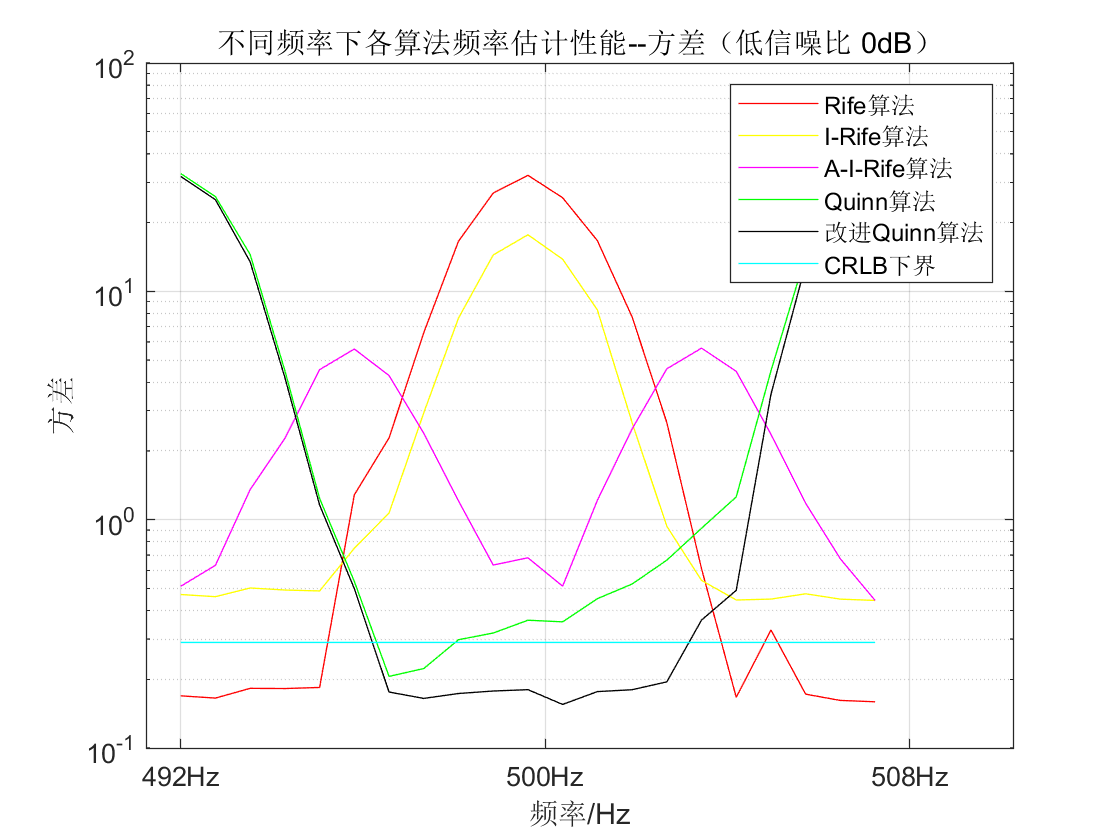

%绘图，方差的仿真图象
figure(2);
%具体采用线性坐标还是对数坐标，要看实际的图像适合哪个，可在图窗界面自行设置选项，以及，曲线的选项同理
semilogy(1:length(f),Var_Rife,'r');
hold on;
semilogy(1:length(f),Var_Irife,'y');
hold on;
semilogy(1:length(f),Var_AIrife,'m');
hold on;
semilogy(1:length(f),Var_Quinn,'g');
hold on;
semilogy(1:length(f),Var_Quinn_About,'k');
hold on;
semilogy(1:length(f),Var_CRLB*ones(1,length(f)),'c');
%以下参数是为了方便手动设置图像的部分选项，仅供参考，可直接忽略，后续可在图窗界面设置
xticks([1 1+length(f)/2 1+length(f)]);
xticklabels({'492Hz','500Hz','508Hz'});
xlabel('频率/Hz');
ylabel('方差');
title('不同频率下各算法频率估计性能--方差（低信噪比 0dB）');
legend('Rife算法','I-Rife算法','A-I-Rife算法','Quinn算法','改进Quinn算法','CRLB下界'); %直接估计的方差不考虑
grid on;

%x轴为不同信噪比/信干比的仿真（适用'窗函数类型'、'信干比'、'噪声类型'、'信噪比'等基于信噪比/信干比的仿真）

f = f0 + delta_f/4; %选择距选定的落于采样点的频点1/4个采样间隔的频点仿真，也可设置其他
% 这里，考虑靠近两谱线中心，各算法差距不大，落于谱线上，各算法相比直接估计性能不能得到明显提升，因此选用1/4个采样间隔点
x_f = A*sin(2*pi*f*t + phi_0); %生成待测信号

%x_I = sin(2*pi*(f+delta_f)*t + pi/2); %干扰信号，此处示例为设置干扰信号距离待测频率一个采样间隔。

snr = 0:0.2:10;%更改待信噪比SNR的范围，所示为从0dB到10dB，以0.2dB为单位等间距取点
sigma = ones(size(snr));%预先设置sigma矩阵的大小
P_signal = 0.5*A^2;%待测信号功率
for j = 1:length(snr) %通过SNR计算sigma值，以便于后续生成噪声。
    sigma(j) = sqrt(P_signal*(10^(-snr(j)/10)));
end

%预先设置窗函数的类型
% window = hann(L);%汉宁窗
% window = hamming(L);%哈明窗
% window = blackman(L);%布莱克曼窗
% window = blackmanharris(L);%布莱克曼-哈里斯窗
% window = kaiser(L);%凯赛窗

%预先设置频率估计RMS值的矩阵大小，用RMS值代表估计频率大小
RMS_Dirc = ones(1,length(snr));%直接估计算法
RMS_Rife= ones(1,length(snr));%Rife算法
RMS_Irife = ones(1,length(snr));%Irife算法
RMS_AIrife = ones(1,length(snr));%AIrife算法
RMS_Quinn = ones(1,length(snr));%Quinn算法
RMS_Quinn_About = ones(1,length(snr));%改进Quinn算法

%预先设置频率估计方差的矩阵大小，用方差衡量频率估计的稳定性
Var_Dirc = ones(1,length(snr));%直接估计算法
Var_Rife= ones(1,length(snr));%Rife算法
Var_Irife = ones(1,length(snr));%Irife算法
Var_AIrife = ones(1,length(snr));%AIrife算法
Var_Quinn = ones(1,length(snr));%Quinn算法
Var_Quinn_About = ones(1,length(snr));%改进Quinn算法

for j = 1:length(sigma)
    x = ones(n,L);
    for k = 1:n
        %选用不同的噪声类型，已预先设置好，使得snr = -20*log10(sigma)
        x(k,:) = x_f + sigma(j)^2*randn([1,L]);%高斯噪声
        %x(k,:) = x_f + sqrt(0.5)*sigma(j)^2*raylrnd(1,[1,L]); %瑞利噪声
        %x(k,:) = x_f + sqrt(0.5)*sigma(j)^2*sqrt(12)*(rand([1,L])-0.5); %平均分布噪声
        %x(k,:) = x_f + sqrt(0.5)*sigma(j)^2*random('Poisson',1,[1,L]); %泊松分布噪声
        
        %x(k,:) = (x_f + sigma(j)^2*randn([1,L])).*window';%加窗函数,附加高斯噪声

        %x(k,:) = x_f + sqrt(2)*sigma(j)*x_I+randn([1,L]); %加干扰信号,附加0dB高斯白噪声
        %同理，已预先设置好使得SIR = 20*log10(sigma)
    end

    %预先设置好频率估计的矩阵大小
    f_est_Dirc = ones(1,n);
    f_est_Rife = ones(1,n);
    f_est_Irife = ones(1,n);
    f_est_AIrife = ones(1,n);
    f_est_Quinn = ones(1,n);
    f_est_Quinn_About = ones(1,n);

    %运行频率估计算法
    for m = 1:n    
        f_est_Dirc(m) = Dirc_esti(x(m,:),t);
        f_est_Rife(m) = Rife_esti(x(m,:),t);
        f_est_Irife(m) = Irife_esti(x(m,:),t);       
        f_est_AIrife(m) = AIrife_esti(x(m,:),t); 
        f_est_Quinn(m) = Quinn_esti(x(m,:),t);
        f_est_Quinn_About(m) = Quinn_About_esti(x(m,:),t);       
    end

    %计算RMS值
    RMS_Dirc(1,j) = sqrt(sum(f_est_Dirc.^2)/n);
    RMS_Rife(1,j) = sqrt(sum(f_est_Rife.^2)/n);
    RMS_Irife(1,j) = sqrt(sum(f_est_Irife.^2)/n);  
    RMS_AIrife(1,j) = sqrt(sum(f_est_AIrife.^2)/n);  
    RMS_Quinn(1,j) = sqrt(sum(f_est_Quinn.^2)/n);
    RMS_Quinn_About(1,j) = sqrt(sum(f_est_Quinn_About.^2)/n);

    %计算方差
    Var_Dirc(1,j) = var(f_est_Dirc);
    Var_Rife(1,j) = var(f_est_Rife);
    Var_Irife(1,j) = var(f_est_Irife);  
    Var_AIrife(1,j) = var(f_est_AIrife);  
    Var_Quinn(1,j) = var(f_est_Quinn);
    Var_Quinn_About(1,j) = var(f_est_Quinn_About);
end

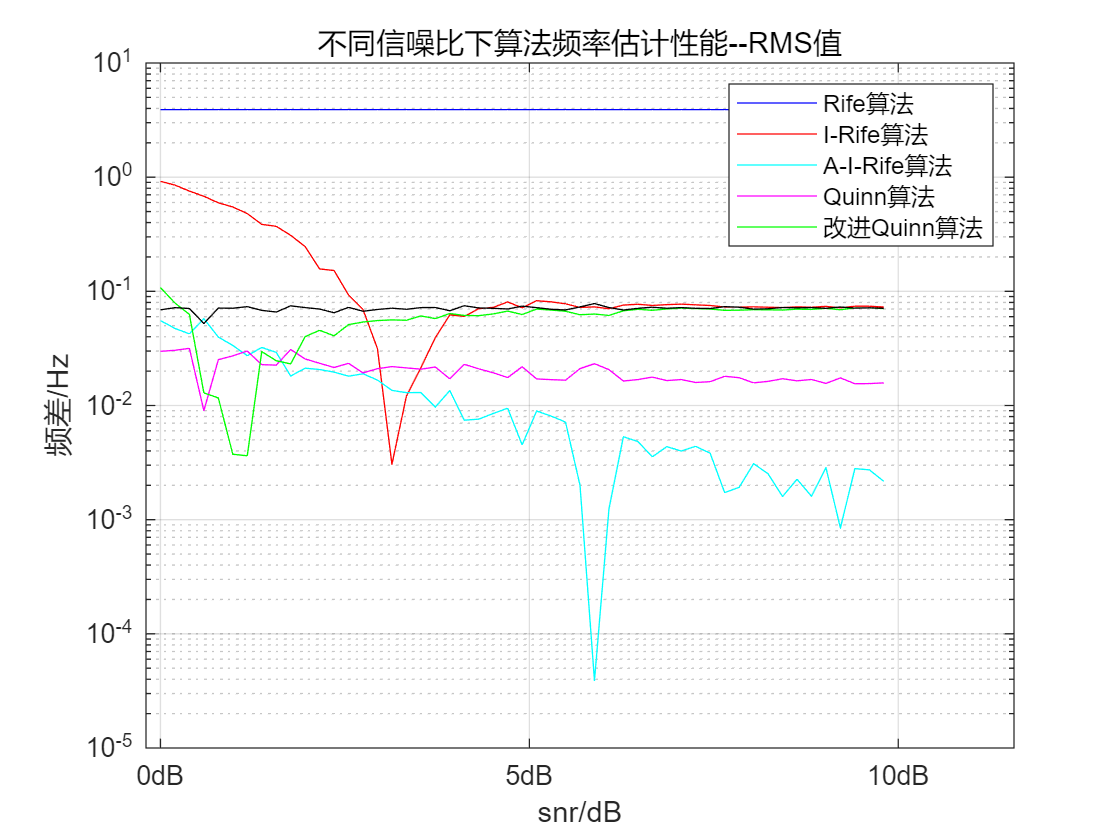

%绘图，RMS值的仿真图象
close all;
figure(3);
%具体采用线性坐标还是对数坐标，要看实际的图像适合哪个，可在图窗界面自行设置选项，以及，曲线的选项同理
semilogy(1:length(snr),abs(RMS_Dirc-f),'b');
hold on;
semilogy(1:length(snr),abs(RMS_Rife-f),'r');
hold on;
semilogy(1:length(snr),abs(RMS_Irife-f),'c');
hold on;
semilogy(1:length(snr),abs(RMS_AIrife-f),'m');
hold on;
semilogy(1:length(snr),abs(RMS_Quinn-f),'g');
hold on;
semilogy(1:length(snr),abs(RMS_Quinn_About-f),'k');
%以下参数是为了方便手动设置图像的部分选项，仅供参考，可直接忽略，后续可在图窗界面设置
xticks([1 1+length(snr)/2 1+length(snr)]);
xticklabels({'0dB','5dB','10dB'});
xlabel('snr/dB');
ylabel('频差/Hz');
title('不同信噪比下算法频率估计性能--RMS值');
legend('Rife算法','I-Rife算法','A-I-Rife算法','Quinn算法','改进Quinn算法');  
grid on;

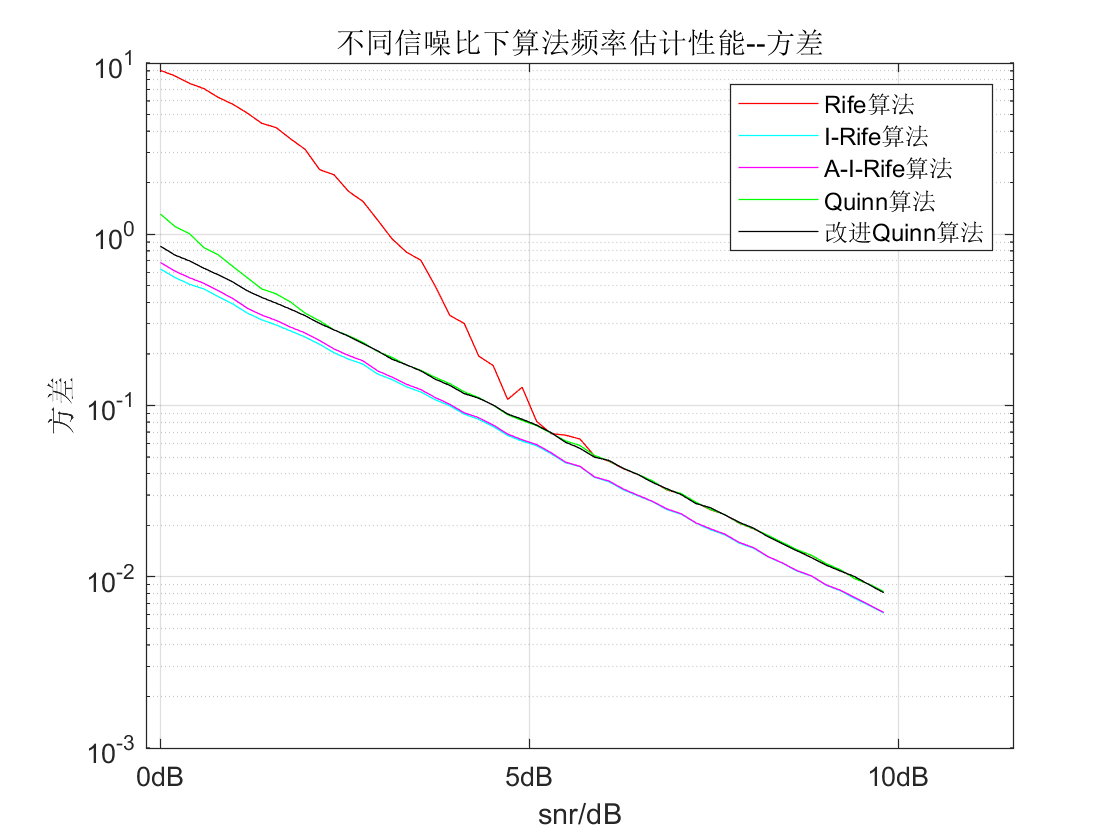

%绘图，方差的仿真图象
figure(4);
%具体采用线性坐标还是对数坐标，要看实际的图像适合哪个，可在图窗界面自行设置选项，以及，曲线的选项同理
semilogy(1:length(snr),Var_Rife,'r');
hold on;
semilogy(1:length(snr),Var_Irife,'c');
hold on;
semilogy(1:length(snr),Var_AIrife,'m');
hold on;
semilogy(1:length(snr),Var_Quinn,'g');
hold on;
semilogy(1:length(snr),Var_Quinn_About,'k');
%以下参数是为了方便手动设置图像的部分选项，仅供参考，可直接忽略，后续可在图窗界面设置
xticks([1 1+length(snr)/2 1+length(snr)]);
xticklabels({'0dB','5dB','10dB'});
xlabel('snr/dB');
ylabel('方差');
title('不同信噪比下算法频率估计性能--方差');
legend('Rife算法','I-Rife算法','A-I-Rife算法','Quinn算法','改进Quinn算法');  %直接估计的方差不考虑
grid on;